# Determine if the Bison Are Coming or Going

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

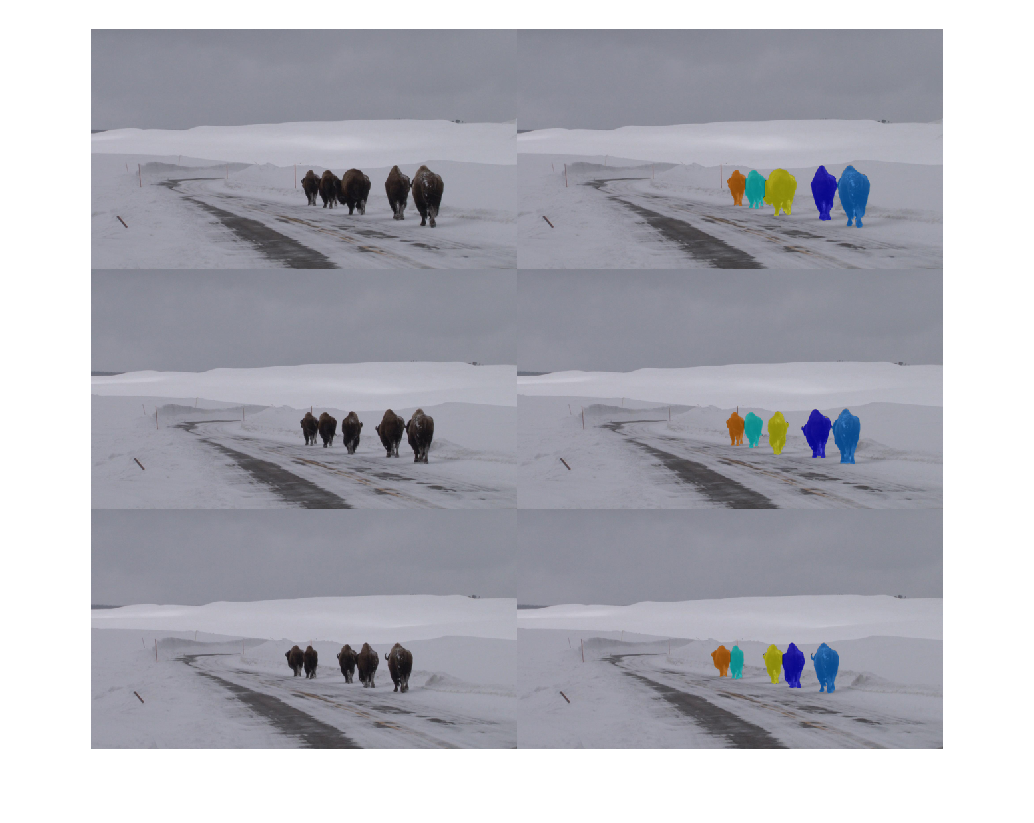

% First frame: image, mask, label image, and overlay image
bison1 = imread("./images/bison1.jpg");
[mask1, labels1] = bisonMaskAndLabel(bison1); % local function at bottom of script
overlay1 = labeloverlay(bison1, labels1);

% Second frame: image, mask, label image, and overlay image
bison2 = imread("./images/bison2.jpg");
[mask2, labels2] = bisonMaskAndLabel(bison2); 
overlay2 = labeloverlay(bison2, labels2);

% Third frame: image, mask, label image, and overlay image
bison3 = imread("./images/bison3.jpg");
[mask3, labels3] = bisonMaskAndLabel(bison3); 
overlay3 = labeloverlay(bison3, labels3);

montage({bison1 bison2 bison3; overlay1 overlay2 overlay3})

## Task 1

The label matrices for the three image frames are created for you. To take a measurement of labeled regions, you can use the `regionprops` function.

`stats` `=` `regionprops``(``output``,``L``,``props``)`

`output` specifies the type of `stats` and is either `"struct"` or `"table"`.  `L` is a label image, and `props` is a string array specifying the properties to return.  

In this image, you can measure the height of the labeled regions with the `"MajorAxisLength"` property.

hts1 = regionprops("table", labels1, "MajorAxisLength")

hts1 = 5×1 table
    MajorAxisLength
    _______________

        155.98     
        168.21     
        202.05     
        238.18     
        264.95     


## Task 2

Each row of the table contains data for a single labeled region. You can calculate the number of rows of a table with the `height` function.

`numRows` `=` `height``(``tbl``)`

numObj = height(hts1)

numObj = 5

## Task 3

hts2 = regionprops("table", labels2, "MajorAxisLength")

hts2 = 5×1 table
    MajorAxisLength
    _______________

         146.7     
        152.79     
        189.79     
        210.74     
        242.47     



hts3 = regionprops("table", labels3, "MajorAxisLength")

hts3 = 5×1 table
    MajorAxisLength
    _______________

         134.4     
        152.45     
        170.48     
        198.39     
        218.95     


## Task 4

You can extract columns of data from a table with dot notation.

`tbl.VarName`

hts = [hts1.MajorAxisLength hts2.MajorAxisLength hts3.MajorAxisLength]

hts =   155.9763  146.6999  134.3997
  168.2108  152.7854  152.4511
  202.0518  189.7940  170.4813
  238.1845  210.7438  198.3930
  264.9493  242.4696  218.9454


## Task 5

Each column contains data from a frame, and each row contains data from a bison.

Passing a matrix to the `plot` function will plot each of the columns as a separate line on the same graph.

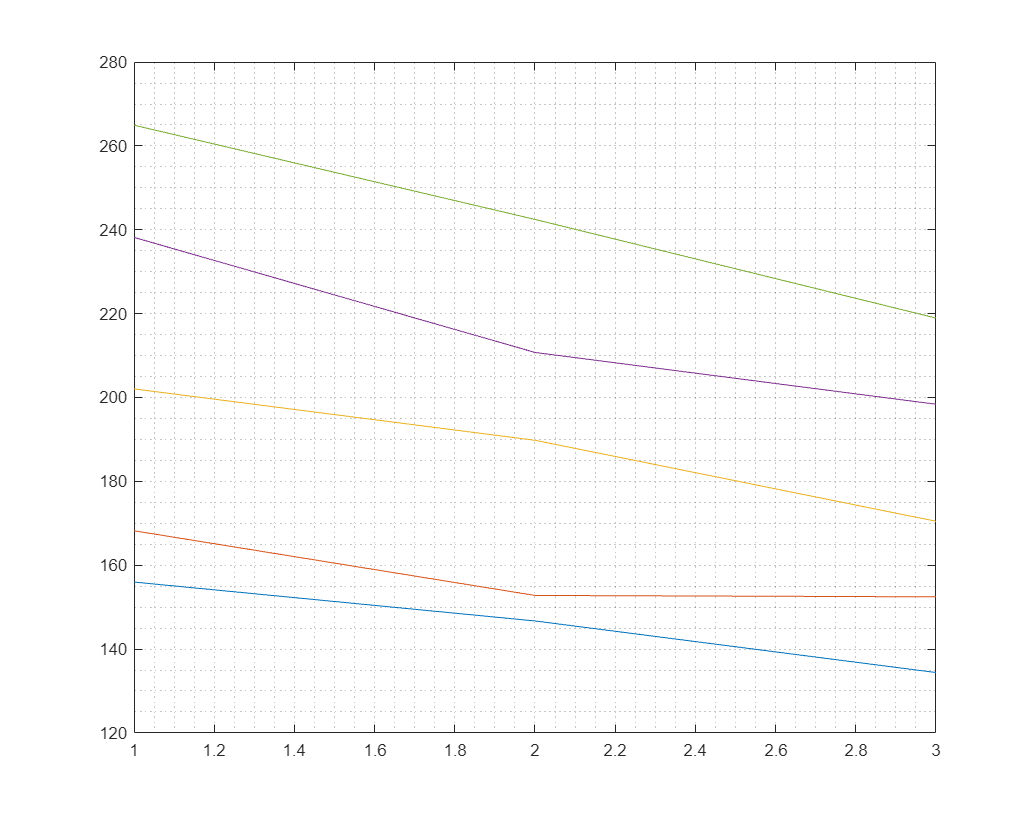

plot(hts')
grid minor

function [mask,labelMatrix] = bisonMaskAndLabel(bison)
    gray = im2gray(bison);
    bisonBW = gray<65;
    
    bisonBW = bwareaopen(bisonBW, 150);
    
    mask = activecontour(bison,bisonBW,"Chan-Vese","ContractionBias", -.25);
    
    mask = imfill(mask, "holes");
    
    se = strel("disk", 3);
    mask = imopen(mask, se);
    
    % create and pre-process grayscale image for watershed
    d = bwdist(~mask);
    d = imcomplement(d);
    
    Ihmin = imhmin(d, 5);
    
    % perform watershed
    labelMatrix = watershed(Ihmin);
    
    % post processing
    labelMatrix(~mask) = 0;
end